# BRAINSTAT Tutorial 

% Ascertain script runs correctly both as live script and regular script.
run_as_live_script = true;
if run_as_live_script
    pretty = @pretty_plot;
else
    pretty = @(x)x;
end

### ------------------------------

### Load sample dataset

### ------------------------------

[cortical_thickness, demographics] = fetch_mics_data();

### -----------------------------------------------------------------------

### Plot cortical thickness using the ENIGMA Toolbox

### -----------------------------------------------------------------------

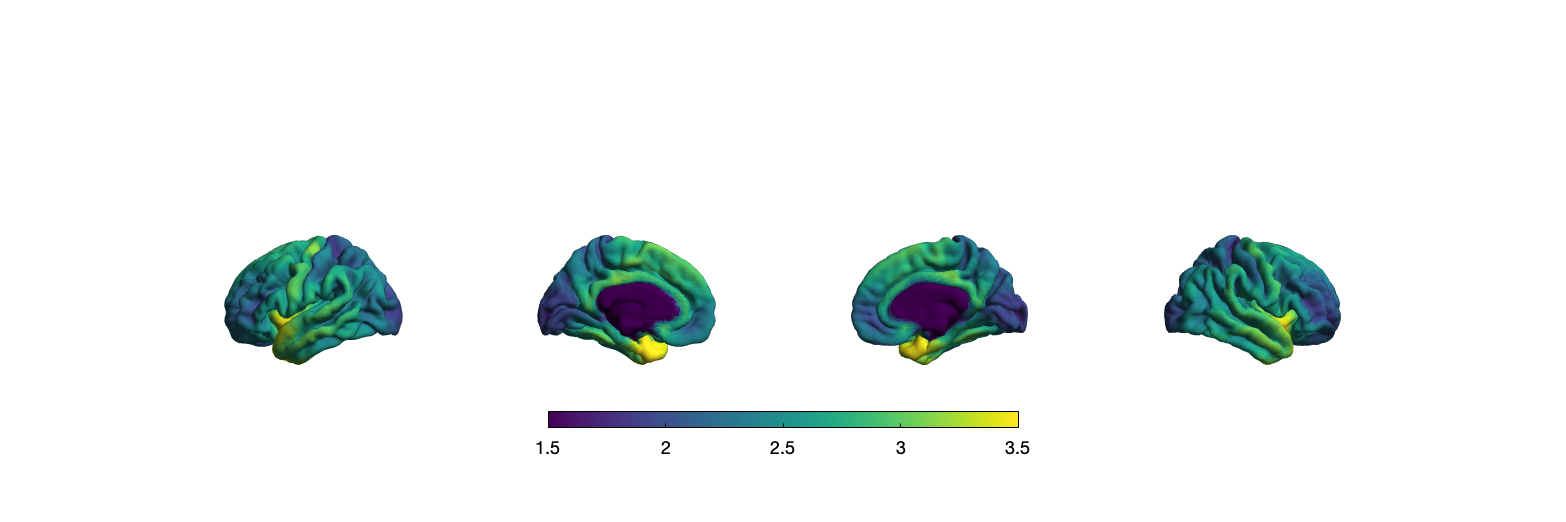

1 x 2 files to read, % remaining: 100 Done


f = figure('Renderer', 'painters', 'Position', [10 10 1200 400]);
plot_cortical(mean(cortical_thickness), 'cmap', 'viridis', ...
    'color_range', [1.5, 3.5]);

### -----------------------------------

### Print demographics data

### -----------------------------------

disp(demographics(1:10,:))

      SUB_ID      VISIT    AGE_AT_SCAN     SEX 
    __________    _____    ___________    _____

    {'031404'}      1          27         {'F'}
    {'04a144'}      1          25         {'M'}
    {'0b78f1'}      1          33         {'M'}
    {'0d26b9'}      1          36         {'F'}
    {'1988b8'}      1          31         {'M'}
    {'219baf'}      1          23         {'M'}
    {'242357'}      1          26         {'F'}
    {'26899f'}      1          24         {'M'}
    {'26899f'}      2          26         {'M'}
    {'29b77c'}      1          23         {'F'}



### --------------------------------------------------------------------------------------

### Create linear model to assess the effect of age on thickness

### --------------------------------------------------------------------------------------

term_age = FixedEffect(demographics.AGE_AT_SCAN, 'Age');
model = term_age;
disp(model)

  82×2 FixedEffect array with properties:

     names: ["intercept"    "Age"]
    matrix: [82×2 double]



### ----------------------

### Fit linear model

### ----------------------

contrast_age = demographics.AGE_AT_SCAN;
mask = fetch_mask('fsaverage5');

slm = SLM( ...
    model, ...
    -contrast_age, ...
    'surf', 'fsaverage5', ...
    'correction', {'rft', 'fdr'}, ...
    'cluster_threshold', 0.01, ...
    'mask', mask);
slm.fit(cortical_thickness);


### ----------------------------

### Plot t- and p-values

### ----------------------------

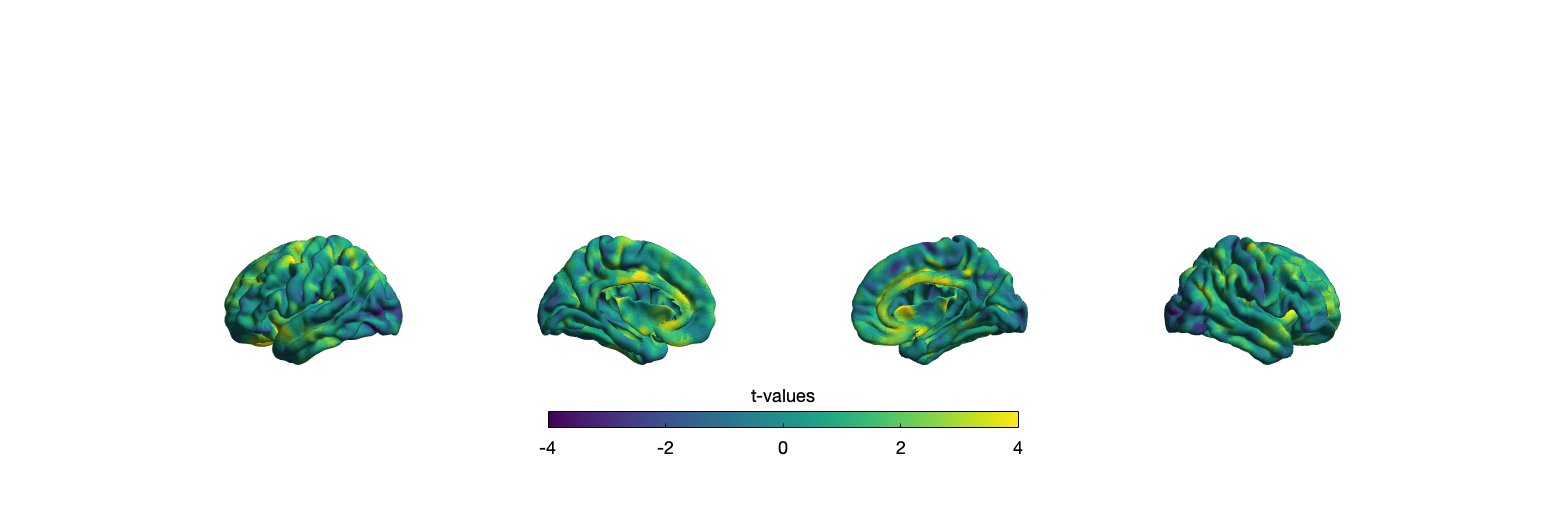

1 x 2 files to read, % remaining: 100 Done


f = figure('Renderer', 'painters', 'Position', [10 10 1200 400]);
plot_cortical(slm.t, 'cmap', 'viridis', 'color_range', [-4, 4], ...
    'label_text', 't-values');

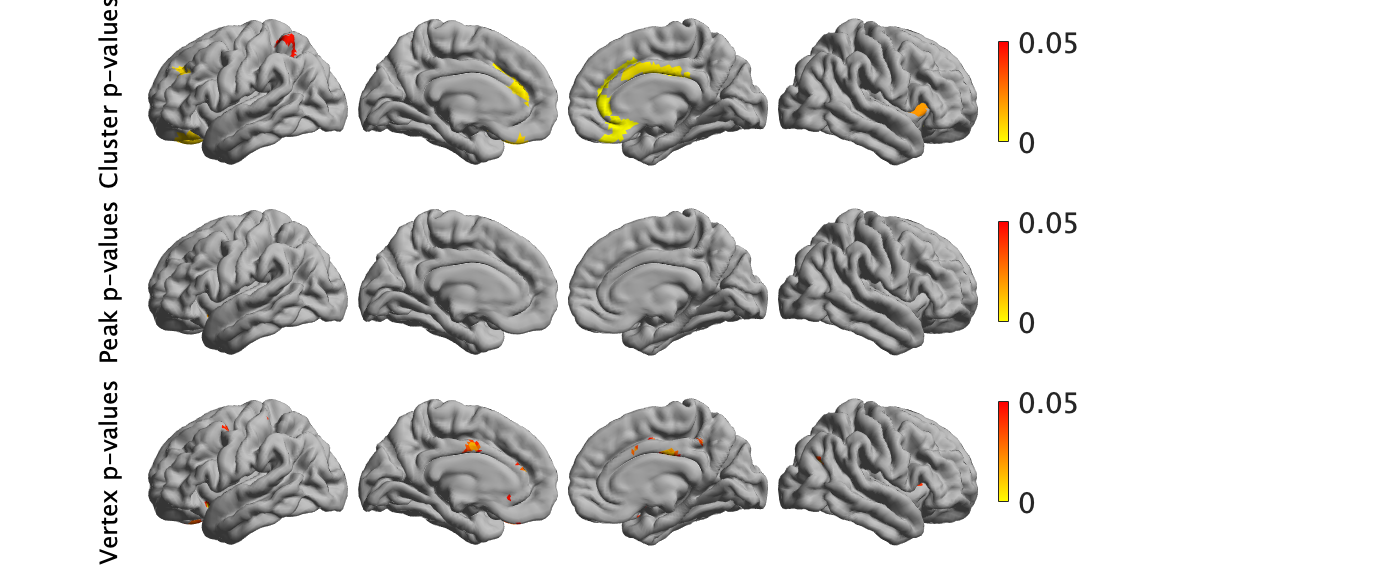

[surf_left, surf_right] = fetch_template_surface('fsaverage5');

pp = slm.P.pval.P(:); pp(~mask, :) = inf;

obj = plot_hemispheres([slm.P.pval.C(:), pp, slm.Q(:)], ...
    {surf_left, surf_right}, 'labeltext', {'', '', ''}, ...
    'labeltext', ["Cluster p-values", "Peak p-values", "Vertex p-values"]); 
obj.colormaps([flipud(autumn); .7 .7 .7]); obj.colorlimits([0, 0.05]); pretty(obj);

### ---------------------------------

### Meta-analytic decoding

### ---------------------------------

[correlation, feature] = meta_analytic_decoder(slm.t, ...
    'template', 'fsaverage5');
disp(correlation(1:3));

    0.2016
    0.2014
    0.1955



disp(feature(1:3));

    {'nucleus accumbens'}    {'accumbens'}    {'subgenual'}



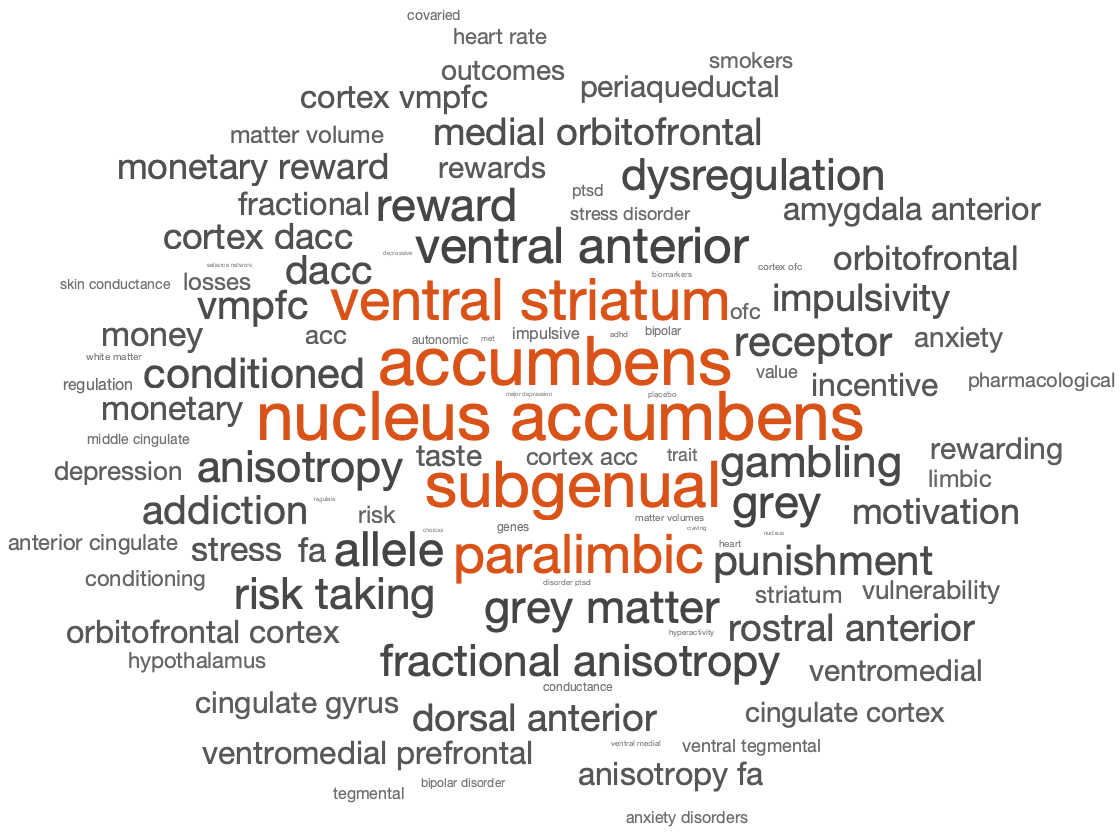

figure();
wc = wordcloud(feature(correlation>0), correlation(correlation>0));

*_________________________________________________________*

*Below is the support function used in this live script. *

function pretty_plot(obj)
% Makes the BrainSpace plots prettier inside live scripts.
obj.handles.figure.Units = 'pixels';
set(obj.handles.axes, 'Units', 'pixels')
set(obj.handles.colorbar, 'Units', 'pixels');
obj.handles.figure.Position = [1, 1, 700, size(obj.data, 2) * 95];
set(obj.handles.text, 'FontSize', 12);

for jj = 1:size(obj.data, 2) % variates
    obj.handles.colorbar(jj).Position = [...
        500, ...
        30 + (size(obj.data, 2) * 95) - 10 - jj*90, ...
        5, ...
        50];
    for ii = 1:4 % views
        obj.handles.axes(jj, ii).Position = [...
            75 + (ii-1)*105, ...
            (size(obj.data, 2) * 95) - jj*95, ...
            100, ...
            100];
    end
end
end